# Classification of a 4-class problem with a perceptron network

This example demonstrates a perceptron network with 2-inputs and 2-outputs which is trained to classify input vectors into 4 categories.

For this purpose, 4 clusters of data, belonging to 4 classes, are defined in 2-dimensional input space. 

The task is to construct a perceptron for the classification of data into two classes.

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Define data

In this section, 2-dimensional data, belonging to 4 classes, are generated. You can modify data-generating parameters (Nclass, offset).

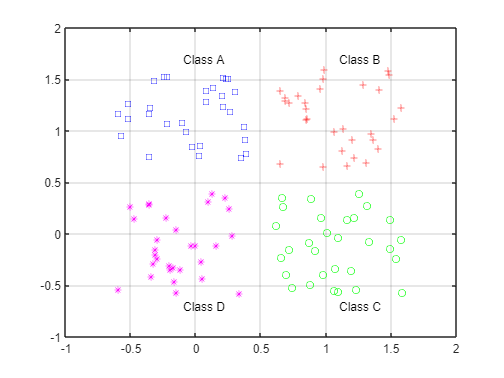

close all, clear all, clc, format compact

Nclass =30; % number of samples of each class
offset =0.6; % offset between classes

% define classes
A = [rand(1,Nclass)-offset; rand(1,Nclass)+offset];
B = [rand(1,Nclass)+offset; rand(1,Nclass)+offset];
C = [rand(1,Nclass)+offset; rand(1,Nclass)-offset];
D = [rand(1,Nclass)-offset; rand(1,Nclass)-offset];

% plot classes
plot(A(1,:),A(2,:),'bs')
hold on
grid on
plot(B(1,:),B(2,:),'r+')
plot(C(1,:),C(2,:),'go')
plot(D(1,:),D(2,:),'m*')

% text labels for classes 
text(.5-offset,.5+2*offset,'Class A')
text(.5+offset,.5+2*offset,'Class B')
text(.5+offset,.5-2*offset,'Class C')
text(.5-offset,.5-2*offset,'Class D')

Plot samples of each class 

## Prepare inputs & outputs for perceptron training

Data from different clusters are collected into two classes of inputs. Outputs are properly encoded using two binary outputs.

% define inputs (combine samples from all four classes)
P = [A B C D];

% define output coding for classes
a = [0 1]';
b = [1 1]';
c = [1 0]';
d = [0 0]';

% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B)) ...
     repmat(c,1,length(C)) repmat(d,1,length(D)) ];

## Create a perceptron

Built-in MATLAB function 'perceptron' is used to construct the perceptron.

net = perceptron;

## Train a perceptron

Then, the perceptron is trained adaptively using the 'adapt' function, and the discriminating functions are plotted during the adaptation process.

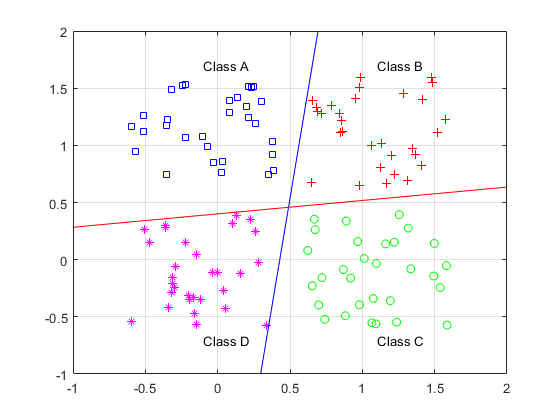

% adaptive training 
E = 1;
net.adaptParam.passes = 1;
linehandle = plotpc(net.IW{1},net.b{1});
n = 0;
while (sse(E) & n<100) 
   n = n+1;
   [net,Y,E] = adapt(net,P,T);
   linehandle = plotpc(net.IW{1},net.b{1},linehandle);
   drawnow;
end

Run the adaptation (and watch the Figure above)

**Notice**: if offset < 0.5, the perceptron will not converge to a solution

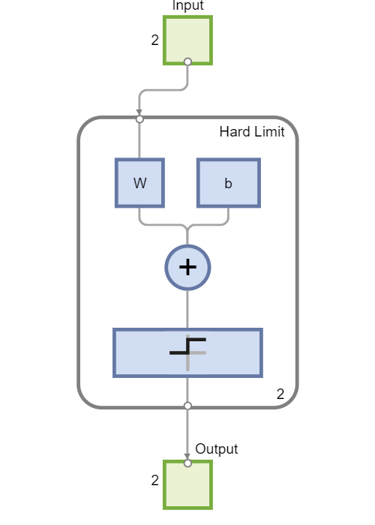

% show perceptron
view(net);

## How to use trained perceptron

The application of the trained perceptron is shown. The input 'p' is applied to the perceptron which calculates the output 'y'. The output is decoded according to the coding scheme (a,b,c,d) into one of the classes (A,B,C,D).

% Define input p = [p1;p2]
p = [1.7; -0.3]

p =     1.7000
   -0.3000


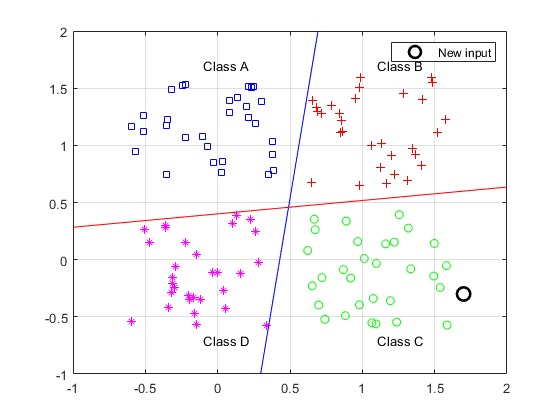

figure(1), hold on

% remove previous input from figure
try delete(f), end 

% plot new input
f = plot(p(1),p(2),'ok','MarkerSize',10,'LineWidth',2);
legend(f,'New input')

Use the trained perceptron to classify a new input p

y = net(p)'

y =      1     0


Compare response y with output coding (a,b,c,d)

if     ~sum(abs(y-a')), disp('Input p is classified as belonging to class A')  % a = [0 1]'
elseif ~sum(abs(y-b')), disp('Input p is classified as belonging to class B')  % b = [1 1]'
elseif ~sum(abs(y-c')), disp('Input p is classified as belonging to class C')  % c = [1 0]'
else   ~sum(abs(y-d')), disp('Input p is classified as belonging to class D')  % d = [0 0]'
end

Input p is classified as belonging to class C


Select a new input 'p' above and run section to classify the new input. 

## PowerPoint presentation

[NN3a_Perceptron_and_Adaline.pptx](matlab:open('./NN3a_Perceptron_and_Adaline.pptx'))